# Relationships between Fourier Transforms and Series

**Learning Goals**

- <LO 1>

- <LO 2>

## Computing the DFT

 **Example.** In this example, the DFT is computed directly from the definition.

**Task.** First, create the data points by running this section.

Fs = 2e3; % Audio sample rate
t = 0:1/Fs:(2-1/Fs); % 2 second time variable
y = sin(2*pi*110*t).*exp(-5*(t-1).^2); % Sampled audio signal (Gaussian-modulated sinusoid)

figure
plot(t,y,'.-')
xlabel("t (s)")
ylabel("y")

Try zooming in on the signal to view the discrete data points $y_n$ that make up this digital audio signal.

**Task. **Run this section to play the generated signal as an audio clip.

% This code will play the audio signal
soundsc(y,Fs)

**Task. **Run this section to compute the DFT using the definition. Note that the [`tic`](https://www.mathworks.com/help/matlab/ref/tic.html) and [`toc`](https://www.mathworks.com/help/matlab/ref/toc.html) functions are used to measure the amount of time required to compute the N-point DFT.

N = numel(y); % The number of samples in y
n = 0:(N-1); % Indices
Y = zeros(N,1);
% Loop through the indices of Yk
tic
for k = 0:(N-1)
    % Compute the sum and put the result in Y
    Y(k+1) = sum( y.*exp(-2*pi*1i*k*n/N) );
end
toc

**Task. **Run this section to plot the real and imaginary components of the result.

plot(real(Y))
hold on
plot(imag(Y))
hold off
xlabel("k")
ylabel("Y_k")

### Fast Fourier Transform (FFT)

In the previous example, the DFT was computed using a for loop, requiring $O(N^2)$ computations. This is very ineffecient relative to the Fast Fourier Transform (FFT). The FFT algorithm breaks up the DFT into smaller DFTs, and then combines the results together to form the full DFT. The FFT requires only $O(N \log(N))$ operations. This implies the FFT can be thousands of times faster than the DFT for large data sets.

 **Exercise.**  In this exercise, you will compute the DFT using the FFT algorithm.

**Task 1.** First, create the data points by running this section.

Fs = 2e3; % Audio sample rate
t = 0:1/Fs:(2-1/Fs); % 2 second time variable
y = sin(2*pi*110*t).*exp(-5*(t-1).^2); % Sampled audio signal (Gaussian-modulated sinusoid)

**Task 2. **Use the [`fft`](https://www.mathworks.com/help/matlab/ref/fft.html) function to compute the DFT of `y` and store the result in Y.

% Write your code here
tic
Y = fft(y);
toc

**Task 3. **Surround the `fft` computation in **Task 2** with the [`tic`](https://www.mathworks.com/help/matlab/ref/tic.html) and [`toc`](https://www.mathworks.com/help/matlab/ref/toc.html) functions to measure how long it takes to compute the fft. Compare this to the amount of time required using the definition in the previous section.

**Task 4. **Plot the real and imaginary components of `Y`. To extract the real and imaginary components, use the [`real`](https://www.mathworks.com/help/matlab/ref/real.html) and [`imag`](https://www.mathworks.com/help/matlab/ref/imag.html) function. Use [`hold`](https://www.mathworks.com/help/matlab/ref/hold.html) commands to continue plotting on the same axes.

% Write your code here
plot(real(Y))
hold on
plot(imag(Y))
hold off
xlabel("k")
ylabel("Y_k")

If correct, your result should be identical to the plot from the previous example.

## Comparing the DFT to the Fourier Transform

The Gaussian-modulated sinusoid is useful for comparing the DFT and Fourier transform because the analytic form of the is known. 

**Task.** Run this section to sample the $g$ and plot its Fourier transform.

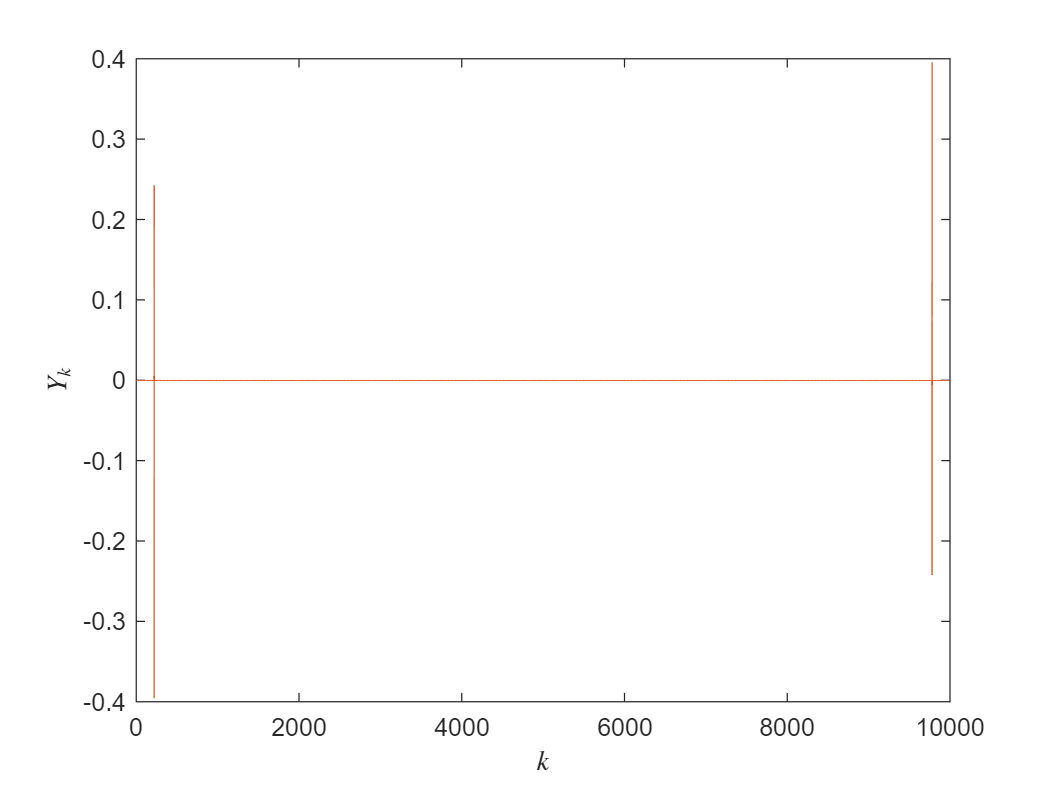

Fs = 2e3; % Audio sample rate
t = 0:1/Fs:(2-1/Fs); % 2 second time variable
y = sin(2*pi*110*t).*exp(-5*(t-1).^2); % Sampled audio signal (Gaussian-modulated sinusoid)
Y = fft(y);
realImagPlot(k,Yrescaled,"$k$","$Y_k$"); % Helper function that creates the plot

You probably noticed that the DFT looks similar to what you'd expect from the Fourier transform of the Gaussian-modulated sinusoid. There's a high frequency peak, which you'd expect to be 110 Hz (the carrier frequency). However, the axes aren't labeled in terms of the frequency $f$ or angular frequency $\omega$, so it's difficult to know for sure. If you zoom in, you can also see that there's what appears to be a Gaussian-modulated sinusoid with real and complex parts, but it appears coarse. Also, notice that the vertical axes are off by 100x.

In order to better understand what is computed by the DFT, it's helpful to look at the analytic Fourier transform for the same function.

**Task. **Run this section to show the analytic plot. 

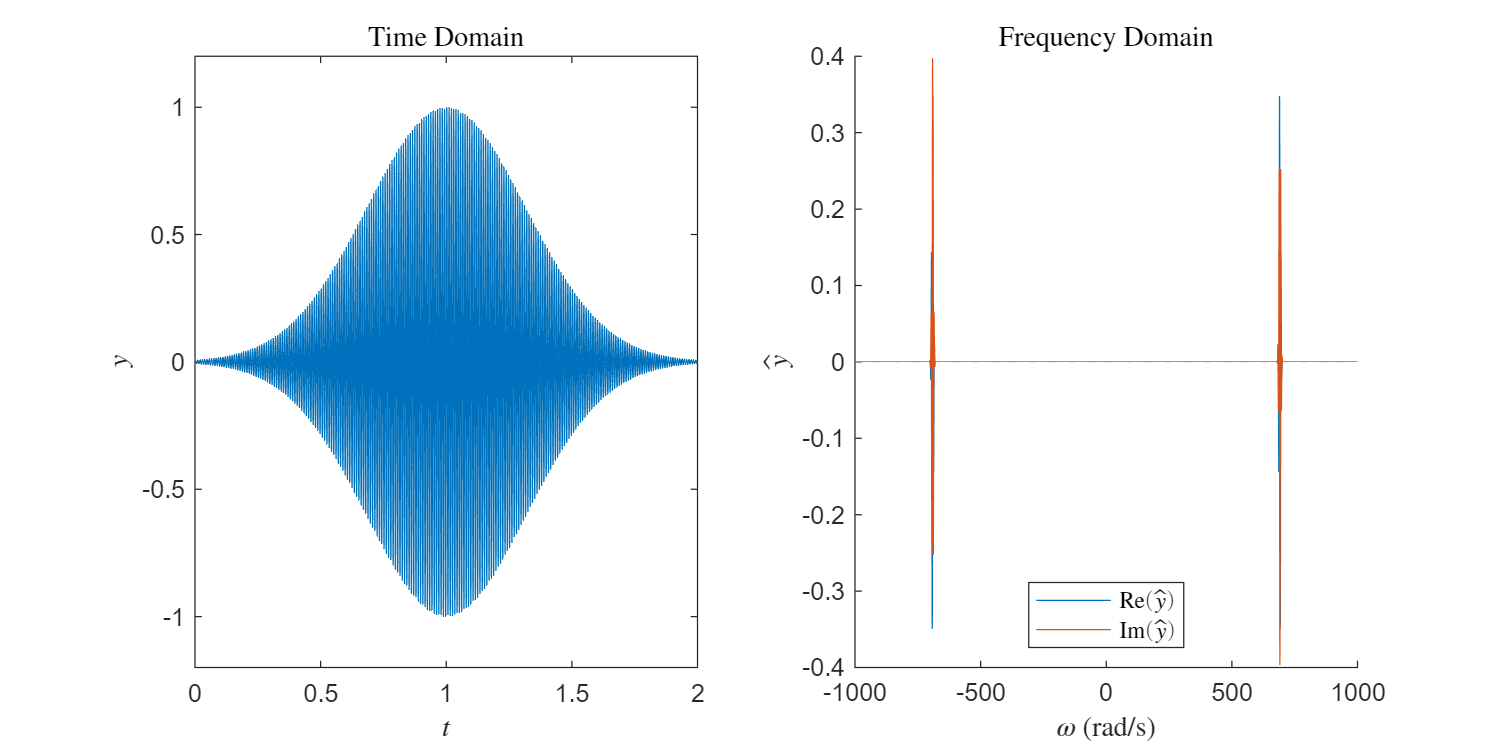

plotFourierTransform

**  Reflect.** 

- Which peaks in the DFT correspond to the peaks of the Fourier transform?

- Zoom in on one of the peaks in the frequency domain (the plot of $\hat{y}$). How does the Fourier transform compare to the  DFT?

To understand the differences, let's compare the DFT and Fourier transform definitions. The DFT:


$$Y_k = \sum_{n = 0}^{N-1} y_n e^{- \frac{ 2 \pi i k n }{N }$$


The Fourier transform:


$$\hat{y}(\omega) = \int_{-\infty}^\infty y(t) e^{-i\omega t} \ dt$$


It's immediately clear that the DFT sum approximates the integral in the analytic Fourier transform. It's also evident that the factors in the DFT are the discrete analogs of the factors in the Fourier transform integrand: $ y_n \leftrightarrow y(t)$ and $e^{- \frac{ 2 \pi i k n }{N }} \leftrightarrow  e^{-i\omega t} \ dt$. 

However, there are two important differences:

- Because the integral is taken with respect to time ($dt$), the scale of $\hat{y}$ will depend on the time scale, while $Y_k$ will not.

- The complex exponential is given in terms of discrete indices: $k$ and $n$, rather than continuous variables, $\omega$ and $t$.

 **Example.** In the example, the DFT will be related to the Fourier transform using the Gaussian-modulated sinusoid.

**Task**. Run this section to compute the DFT using the [`fft`](https://www.mathworks.com/help/matlab/ref/fft.html) function.

Fs = 5e3; % Audio sample rate
t = 0:1/Fs:(2-1/Fs); % 2 second time variable
y = sin(2*pi*110*t).*exp(-5*(t-1).^2); % Sampled audio signal (Gaussian-modulated sinusoid)
Y = fft(y);

The Fourier transform is scaled (in amplitude) by $dt$. The discrete analog of $dt$ is the time step $\Delta t$ in the sampled signal. The time step $\Delta t = 1/ f_s$, where $f_s$  is the sampling frequency. This implies that, to rescale the output $Y$ to match $\hat{y}$, you can multiply by `1/Fs`.

**Task. **Run this section to rescale `Y` and plot the result. Compare the vertical axis scale to result of the analytic Fourier transform.

N = length(Y);
k = 0:(N-1);
Yrescaled = 1/Fs*Y;
realImagPlot(k,Yrescaled,"$k$","$\frac{1}{f_s}Y_k$"); % Helper function that creates the plot

You can also use the sample rate `Fs` to relate the discrete indices $k$ and $n$ to the continuous variables $\omega$ and $t$. Equating these terms in the exponentials of each definition:


$$  \frac{2 \pi kn}{N} = t \omega$$


The discretized version of $t$ is $n \Delta t  = n / f_s$, so


$$\frac{2 \pi kn}{N} = \frac{n}{f_s} \omega$$


So the discrete frequencies used by the DFT are


$$\omega_k = \frac{ 2 \pi k f_s}{   N}$$


**Task. **Run this section to plot the DFT result against the angular frequencies $\omega_k$.

omega = 2*pi*k*Fs/N;
realImagPlot(omega,Yrescaled,"$\omega$","$\frac{1}{f_s}Y_k$"); % Helper function that creates the plot

Compare the angular frequencies of the DFT to those of the Fourier transform. Are the peaks in the same location? You can identify the locations of the peaks by clicking on the graph to create a tooltip. 

You should notice that the **first **peak of the DFT matches the **second** peak of the Fourier transform. Why does this happen? In the DFT definition:


$$Y_k = \sum_{n = 0}^{N-1} y_n e^{- \frac{ 2 \pi i k n }{N }$$


Only positive frequencies are computed. This means that the first value of the DFT, $Y_0$, corresponds to $\omega = 0$. Compare that to the Fourier transform, which is plotting both negative and positive frequencies.

So, how do you relate the two? It turns out that the discrete Fourier transform copies the negative frequency peak to high frequencies. This is one of the greatest points of confusion for the DFT, and it will be discussed in more detail later. In order to adjust the DFT so it better matches the Fourier transform, you shift the second half of the computed points to negative frequencies.

**Task. **Run this section to move the high frequency copy to negative frequencies and plot the result. Note that you could also use [`fftshift`](https://www.mathworks.com/help/matlab/ref/fftshift.html) to shift the values of $\{ Y_k \}$ (the function exists for this purpose).

% Shift the Y-values
Yshift = [Yrescaled(N/2+1:N),Yrescaled(1:N/2)];
% Shift omega
omegaShift = 2*pi*Fs/N*(-N/2+1:N/2);

realImagPlot(omegaShift,Yshift,"$\omega$","$\frac{1}{f_s}Y_k$"); % Helper function that creates the plot
xlim([-1000,1000])


Helper Functions

function realImagPlot(x,y,xLabel,yLabel)
    figure
    plot(x,real(y))
    hold on
    plot(x,imag(y))
    hold off
    xlabel(xLabel,"Interpreter","latex")
    ylabel(yLabel,"Interpreter","latex")
end

function plotFourierTransform

    % Parameters
    A = 1;
    f0 = 110;
    c = 1/sqrt(10);
    t0 = 1;
    omega0 = f0*2*pi; % Angular frequency (rad/s)

    % Plot parameters
    omegaLims = [-1000,1000];
    tlims = [0,2];
    ylims = [-1.2,1.2];

    % Compute g
    t = linspace(tlims(1),tlims(2),5e3);
    g = A*sin(omega0*t).*exp(-(t-t0).^2/(2*c^2));

    % Compute transform
    omega = linspace(omegaLims(1),omegaLims(2),5e3);
    ghat = -A*sqrt(pi/2)*1i*c.*(exp(-0.5*(omega-omega0).*(c^2*omega-c^2*omega0+2*t0*1i)) - ...
        exp(-0.5*(omega+omega0).*(c^2*omega+c^2*omega0+2*t0*1i)));

    % Plots a Gaussian modulated sinusoid
    % in time and frequency domains (real/imaginary part)
    figure("Position",[1 1 800 400])
    
    subplot(1,2,1)
    plot(t,g)
    ylim(ylims)    
    xlim(tlims)
    xlabel("$t$","Interpreter","latex")
    ylabel("$y$","Interpreter","latex")
    title("Time Domain","Interpreter","latex")
    
    subplot(1,2,2)
    hold on
    plot(omega,real(ghat))
    plot(omega,imag(ghat))
    xlim([omega(1),omega(end)])
    xlabel("$\omega$ (rad/s)","Interpreter","latex")
    ylabel("$\hat{y}$","Interpreter","latex")
    legend("Re$(\hat{y})$","Im$(\hat{y})$","Interpreter","latex","Location","south");
    title("Frequency Domain","Interpreter","latex")

end